Surf plots for the range of parameters in Section 2

The objective here is to show that the surfaces are smooth so we can get away with a simple hill-climbing algorithm to find the maximum

"dat" can be a combination of dat2 and dat2_kin tables

%Run sims for a spread of kinetic values
if ~exist('ivd','var')
    load([datadir '\ivd.mat']);
end
%cut off the comparison when growth stops
ivd.denhaan.cydat = ivd.denhaan.cydat(1:8);
ivd.denhaan.ctdat = ivd.denhaan.ctdat(1:8);
ivd.denhaan.gdw = ivd.denhaan.gdw(1:8);

if ~exist('remcfg','var')
    load('remoteconfig.mat');
end

v_default.alpha =args.p2.v.alpha;
v_default.addEnzymeToMaint = args.p2.v.addEnzymeToMaint;

v_default.initcellulose = args.p2.v.initcellulose;
args.p2.v.km_cel = 2.6357e-4;
args.p2.v.kcat_cel = 87.5022;
args.p2.v.maxcycles = 1000;
args.p2.model = model_default;
args.p2.v.alpha = 0.0031984;
dat2_surface = table();
layouts_surface = cell(0);


%kms = 2.^(0:-1:-18);
%kcats = 2.^(0:.5:8);

kms = 2.^(-17:-1:-22);
kcats = 2.^(7:.5:10);


for i = 1:length(kms)
    for j = 1:length(kcats)
        args.p2.v.km_cel = kms(i);
        args.p2.v.kcat_cel = kcats(j);
        layout_temp = part2_litParams_generation_remote(args.p2);
        layouts_surface = [layouts_surface {layout_temp}];
    end
end

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

[layouts_surface,remcfg] = runCometsRemotely(layouts_surface,remcfg);

Creating Comets file batch 200713152406
Use this to instantiate the SSH Agent:
eval `ssh-agent`;ssh-add C:/sync/biomes/scripts/remote/keys/id_rsa_noprompt
 
Execute the following to copy files to remote, or run pushcomets.sh:
scp -r ./200713152406 mquintin@scc1:/usr3/graduate/mquintin/cometsremote/200713152406
 
Execute the following to execute COMETS, or run runremotecomets.sh:
ssh mquintin@scc1 'qsub /usr3/graduate/mquintin/cometsremote/200713152406/cometsremote.sh'
 
Execute the following after run completion to recieve output logs, or run pullcomets.sh:
scp -r mquintin@scc1:/usr3/graduate/mquintin/cometsremote/200713152406/log* ./200713152406
 
Remember to kill the SSH Agent when you're done (remember to use 'ps aux' to find stray agents:
kill $SSH_AGENT_ID



dat2_surface = part2_litParams_parseRemoteResults(args.p2,layouts_surface,remcfg.batchnum);
[nrows,~] = size(dat2_surface);
layouts_surface = dat2_surface.layout;
dat2_surface.layout = cell(nrows,1);
dat2_surface.enzymeInMaint = repmat(args.p2.v.addEnzymeToMaint,nrows,1);
dat2_surface.variableInitEnzyme = repmat(args.p2.variableInitEnzyme,nrows,1);
dat2_surface.anaerobic = repmat(args.p2.v.anaerobic,nrows,1);
dat2 = dat2_surface;


%cleanup
dat = dat2_surface;
dat = dat(dat.kcat_cel <= 600,:);
%remove outliers
dat.valid = ones(size(dat.alpha));
%dat.valid((dat.km_cel == .125) & (dat.kcat_cel == 181.0193))= 0;
dat.valid(67) = 0;
dat.valid(140) = 0;

dat = dat(dat.valid == 1,:);

%Calculate the RMSE of the log biomass vs experimental data
[nrows,~] = size(dat);
rmse = zeros(nrows,1);
for i = 1:nrows
    t_exp = ivd.denhaan.ctdat;
    b_exp = ivd.denhaan.gdw;
    t_sim = dat.t{i};
    b_sim = dat.biomass{i};
    b_sim = b_sim(ismember(t_sim,t_exp));
    logbexp = log10(b_exp);
    logbsim = log10(b_sim);
    summation = 0;
    n = length(logbexp);
    for j = 1:n
        val = logbsim(j) - logbexp(j);
        val = val^2;
        summation = summation + val;
    end
    rmse(i) = sqrt(summation/n);
end
dat.rmse = rmse;


alphas = log(unique(dat.alpha));
a = mode(dat.alpha);
log(a)

ans = -5.7451

d = dat(dat.alpha == a,:);
kcat = d.kcat_cel;
km = d.km_cel;
rmse = d.rmse;

%is the plateau actually flat? if yes, this sum should be high
sum(rmse == min(rmse))

ans = 1

f = find(rmse == min(rmse))

f = 304

for i = f
    kcat_km_rmse = [kcat(i), km(i), rmse(i)]
end

kcat_km_rmse =   256.0000    0.0000    0.4083


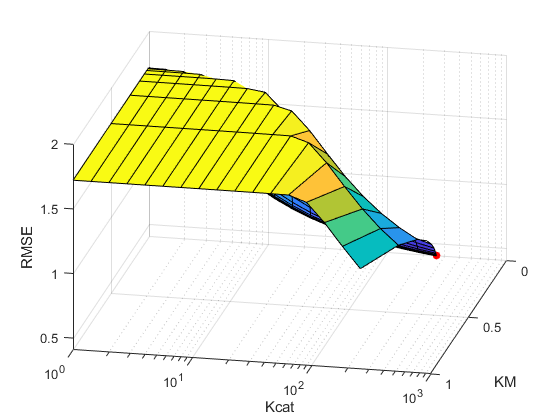

figure();
h = axes;
[p,X,Y,Z] = surfArrays(kcat,km,rmse);
xlabel('Kcat');
ylabel('KM');
zlabel('RMSE');
set(h,'Xdir','reverse');
set(h,'XScale','log');
hold on;
for i = f
    scatter3(kcat(i),km(i),rmse(i),'r','filled')
end
hold off;

view([-168.00000 29.40000])

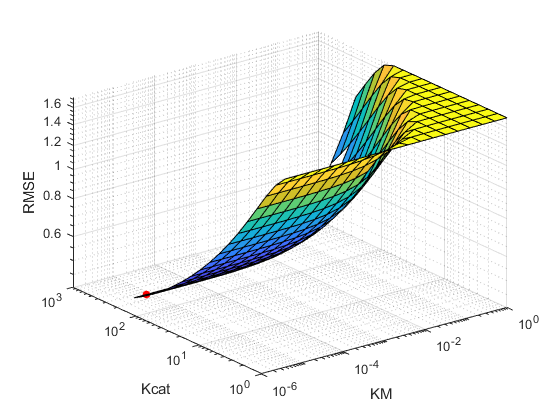


figure();
h = axes;
[p,X,Y,Z] = surfArrays(km,kcat,rmse);
ylabel('Kcat');
xlabel('KM');
zlabel('RMSE');
%set(h,'Xdir','reverse');
set(h,'YScale','log');
set(h,'XScale','log');
set(h,'Zscale','log');
hold on;
for i = f
    scatter3(km(i),kcat(i),rmse(i),'r','filled')
end
hold off;

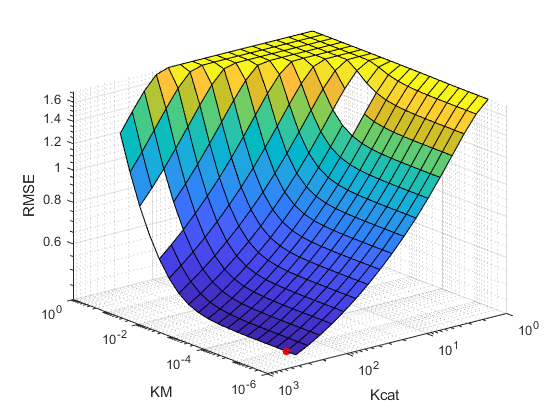


view([-129.058 24.708])

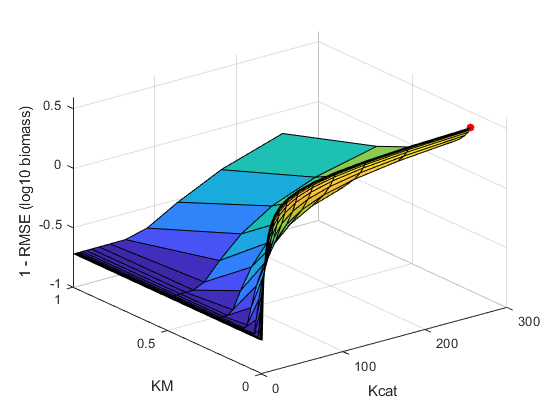


[p,X,Y,Z] = surfArrays(kcat,km,1-rmse);
xlabel('Kcat');
ylabel('KM');
zlabel('1 - RMSE (log10 biomass)');
hold on;
for i = f
    scatter3(kcat(i),km(i),1-rmse(i),'r','filled')
end
hold off;